# Assignment 3 - Question 4 - Reza Mansouri - 002784647

Reading the video:

vidReader = VideoReader('./input/video.mp4','CurrentTime',0);

Specifying the optical flow estimation method as `opticalFlowHS`.

opticFlow = opticalFlowHS

opticFlow =   opticalFlowHS with properties:

            Smoothness: 1
          MaxIteration: 10
    VelocityDifference: 0


1. Plotting the optical flow vectors when treating every previous frame as a reference frame.

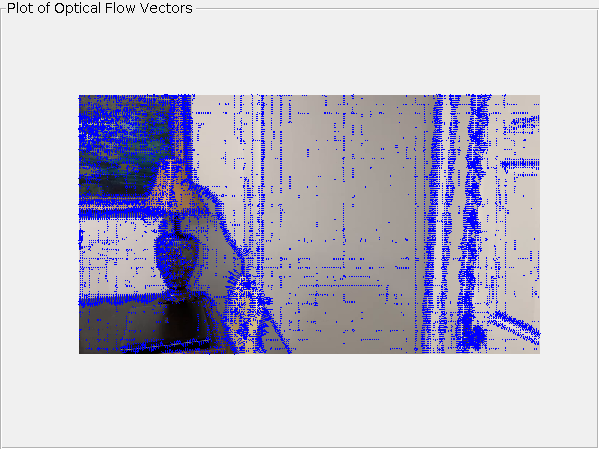

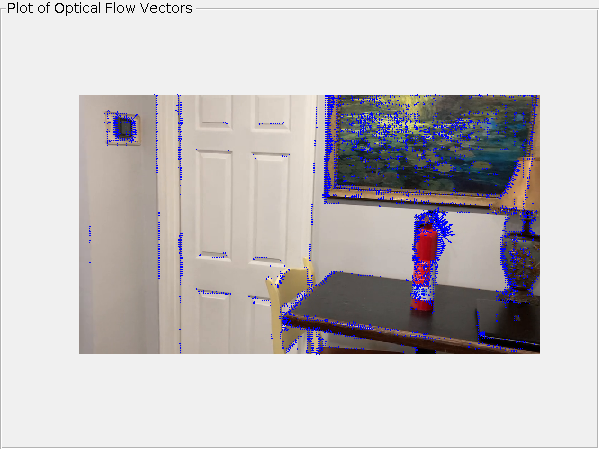

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = im2gray(frameRGB);  
    flow = estimateFlow(opticFlow,frameGray);
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot);
    hold off
    pause(10^-3)
end

opticFlow.reset();
vidReader = VideoReader('./input/video.mp4','CurrentTime',0);

2. Plotting the optical flow vectors when treating every 11th frame as a reference frame.

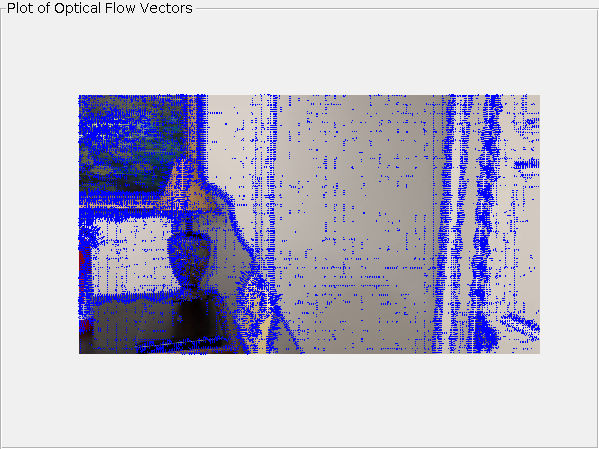

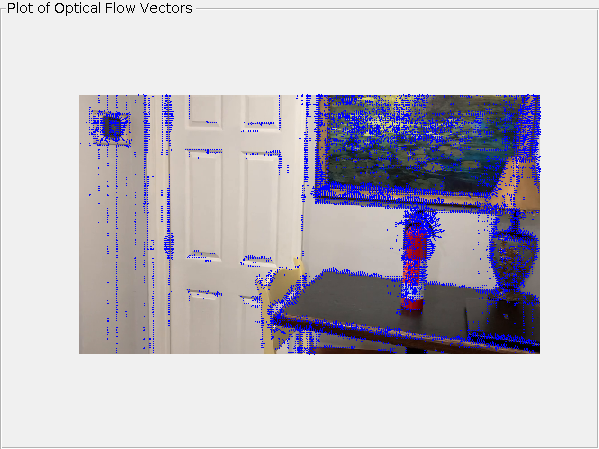

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);
frameCount = 0;

while hasFrame(vidReader)
    frameCount = frameCount + 1;
    if mod(frameCount, 11) == 0
        frameRGB = readFrame(vidReader);
        frameGray = im2gray(frameRGB);  
        flow = estimateFlow(opticFlow,frameGray);
        imshow(frameRGB)
        hold on
        plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot);
        hold off
        pause(10^-3)
    end
end

opticFlow.reset();
vidReader = VideoReader('./input/video.mp4','CurrentTime',0);

3. Plotting the optical flow vectors when treating every 31st frame as a reference frame.

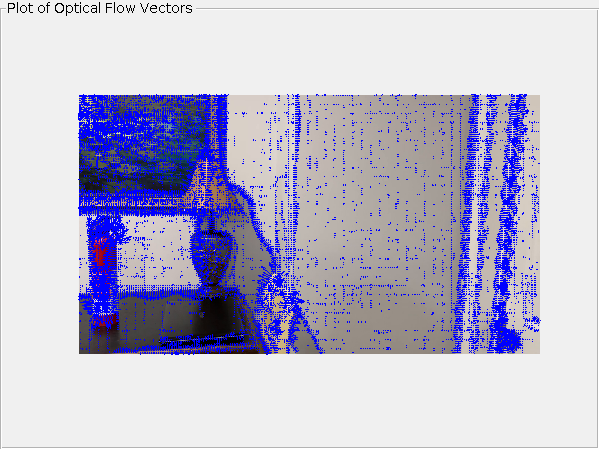

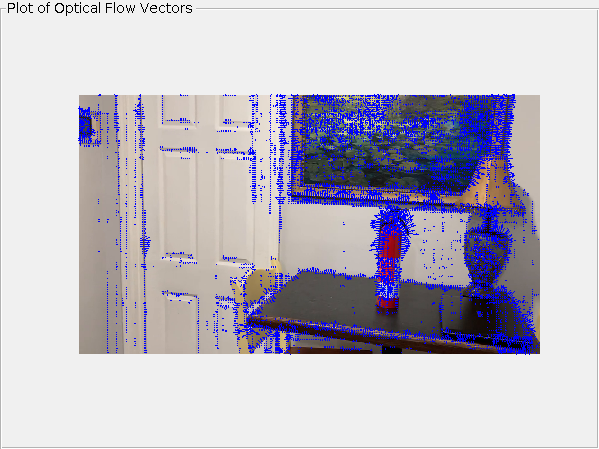

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

frameCount = 0;

while hasFrame(vidReader)
    frameCount = frameCount + 1;
    frameRGB = readFrame(vidReader);
    if mod(frameCount, 31) == 0
        frameRGB = readFrame(vidReader);
        frameGray = im2gray(frameRGB);  
        flow = estimateFlow(opticFlow,frameGray);
        imshow(frameRGB)
        hold on
        plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot);
        hold off
        pause(10^-3)
    end
end

opticFlow.reset();
vidReader = VideoReader('./input/video.mp4','CurrentTime',0);